There are currently 3 defined kernel types:

EQ - exponential Quadratic (SE squared exponential)

RQ - Rational Quadratic (alpha=1)

Matern52

These kernels can be added subtracted multiplied and divided

The GP class takes a mean function and a kernel.

it then can be conditioned on data x and y and can then be trained using mean aposteriori HP selection.

clear

f1 = @(x) (6*x-2).^2.*sin(12*x-4);%.*sin(24*x-1);

xx = linspace(0,1,100)';
yy = f1(xx);

x1 = [0; 1*lhsdesign(3,1);1];
y1 = f1(x1)+normrnd(0*x1(:,1),0*x1(:,1));

%a = means.linear(4)*means.sine(1,3,0,1)
%a = means.sine(1,3,0,1);
a = means.zero()

a =   zero with properties:

         meanz: {[1×1 means.zero]}
        coeffs: {[0]}
    operations: []



%a = means.linear(1.5)*means.linear(0.4) + means.linear(1.6);

b = kernels.EQ(1,0.5);
%b = kernels.LPEQ(1,[0.5 2 2]);
%d = c*b

%b = kernels.JumpRELU(0.5,2,0.1)*kernels.LPEQ(0.5,[2 0.5 2]);

d = b;

d.signn = eps;

Z = GP(a,d);

Z1 = Z.condition(x1,y1);

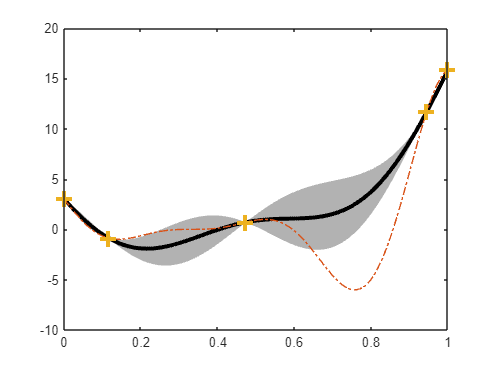

figure
utils.plotLineOut(Z1,1,1)
hold on
plot(xx,yy,'-.')
plot(x1,y1,'+','MarkerSize',12,'LineWidth',3)

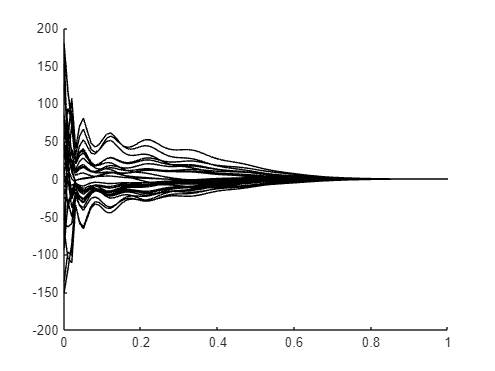

figure
hold on

for i = 1:30
    ysamp = Z1.samplePrior(xx);
    plot(xx,ysamp,'LineWidth',0.05,'Color','k')
end

tic
[Z2] = Z1.train();
toc

Elapsed time is 0.756182 seconds.


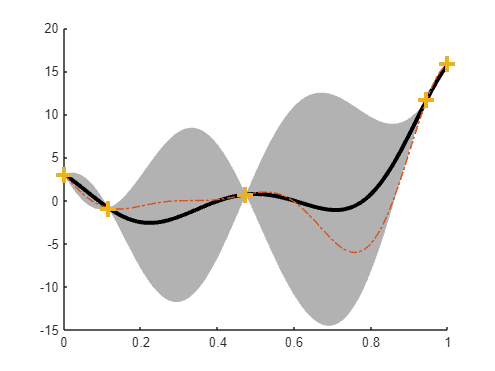

figure
hold on
utils.plotLineOut(Z2,1,1)
plot(xx,yy,'-.')
plot(x1,y1,'+','MarkerSize',12,'LineWidth',3)

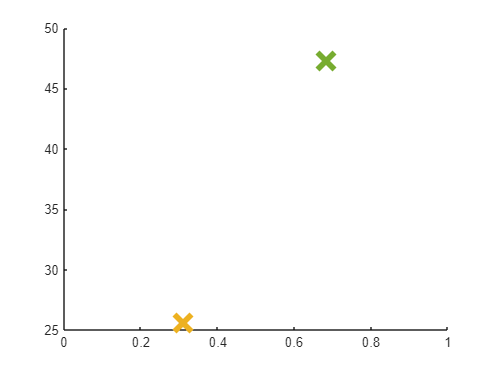

figure
hold on
tic
for i = 1:5
    [x{i},R{i}] = BO.argmax(@BO.maxVAR,Z2);
    plot(x{i},R{i},'x','MarkerSize',18,'LineWidth',4)
end
xlim([0 1])

toc

Elapsed time is 0.153444 seconds.


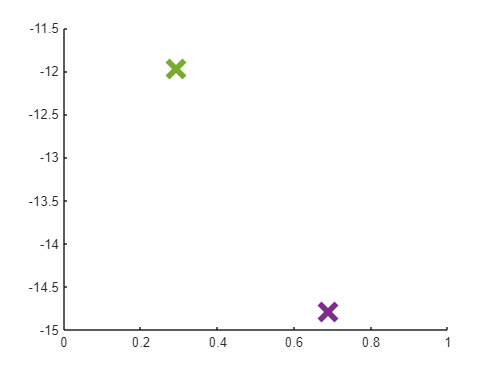

figure
hold on
tic
for i = 1:5
    [x{i},R{i}] = BO.argmin(@BO.LCB,Z2);
    plot(x{i},R{i},'x','MarkerSize',18,'LineWidth',4)
end
xlim([0 1])

toc

Elapsed time is 0.193121 seconds.


tic
[E,V] = Z2.NormalQuadrature(0.5,1)

E = 13.0292

V = -81.5693

toc

Elapsed time is 0.018711 seconds.
